## **Nombres: **

- **Jorge Fernando Bustos Mendez (221160068)**

- **Nicolas Narvaez Arturo (221160075)**

# **Convolución discreta y Filtro digital**

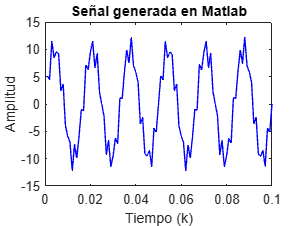

Ts=0.001; Fs=1/Ts;
for k = 1:100
x(k) = 10*sin(2*pi*60*Ts*k);
r(k) = 2.5*sin(2*pi*400*Ts*k);
t(k) = Ts*k;
xr(k) = x(k)+r(k);
end
plot(t,xr,'b')
title('Señal generada en Matlab')
xlabel('Tiempo (k)')
ylabel('Amplitud')

filtro = designfilt('lowpassfir' ...
    ,'FilterOrder',15, ...
    'PassbandFrequency',100, ...
    'StopbandFrequency',150, ...
    'DesignMethod','ls', ...
    'SampleRate',1000);

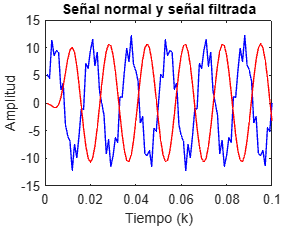

y = filter(filtro,xr);
hold on;
plot(t,y,'r')
title('Señal normal y señal filtrada')
xlabel('Tiempo (k)')
ylabel('Amplitud')

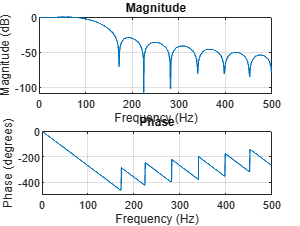

figure(2);
freqz(filtro.Coefficients,1,[],Fs);

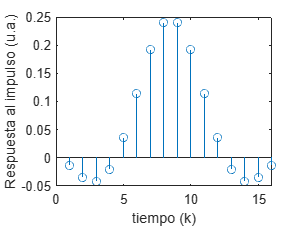

figure(3);
stem(filtro.Coefficients)
xlabel('tiempo (k)');
ylabel('Respuesta al impulso (u.a.)')